M = 6.6102

M = 6.6102

g = 9.8

g = 9.8000

W = M*g

W = 64.7800

rho = 1.225

rho = 1.2250

v_stall = 10/1.2

v_stall = 8.3333

v_cruise = 17

v_cruise = 17

v_climb = 17.6 

v_climb = 17.6000

v_loiter = 20.52

v_loiter = 20.5200

C_L_max = 1.4

C_L_max = 1.4000

C_l_cruise =0.556

C_l_cruise = 0.5560

TO_dist = 200

TO_dist = 200

Power = 500

Power = 500

Clearance = 50

Clearance = 50

C_L_max_land = 2

C_L_max_land = 2

AR = 7.175

AR = 7.1750

e = 0.7

e = 0.7000

k = 0.063377

k = 0.0634

C_d_0 = 0.018606

C_d_0 = 0.0186

For stall

W_S_stall = 0.5*rho*v_stall^2*C_L_max

W_S_stall = 59.5486

S_stall = W/W_S_stall

S_stall = 1.0879

data2 = readtable("Extra pics\graph1.xlsx")

data2 = 78×5 table
     Var1      Var2      Var3     Var4      Var5  
    ______    _______    ____    ______    _______

    100.49    0.63634    NaN     96.487     0.8842
    107.82    0.68876    NaN     103.71    0.94979
    115.16     0.7438    NaN     110.94     1.0154
    122.49    0.79885    NaN     118.06      1.081
    129.83    0.85653    NaN     125.18     1.1492
    137.16    0.91157    NaN      132.3     1.2174
     144.5    0.96399    NaN     139.42     1.2857
    151.83     1.0164    NaN     146.53     1.3539
    159.06     1.0741    NaN     153.65     1.4221
     166.4     1.1318    NaN     160.88     1.4903
    173.73     1.1894    NaN        168     1.5559
    181.06     1.2445    NaN     175.12     1.6268
     188.4     1.2995    NaN     182.23     1.6977
    195.63     1.3572    NaN     189.35     1

para1 = rmmissing(table2array(data2(:,"Var1")))

para1 =   100.4865
  107.8222
  115.1572
  122.4923
  129.8267
  137.1618
  144.4974
  151.8331
  159.0611
  166.3955


dist1 = 1000*rmmissing(table2array(data2(:,"Var2")))

dist1 = 1.0e+03 *

    0.6363
    0.6888
    0.7438
    0.7988
    0.8565
    0.9116
    0.9640
    1.0164
    1.0741
    1.1318


para2 = table2array(data2(:,"Var4"))

para2 =    96.4867
  103.7128
  110.9388
  118.0583
  125.1772
  132.2961
  139.4150
  146.5339
  153.6528
  160.8782


dist2 = 1000*table2array(data2(:,"Var5"))

dist2 = 1.0e+03 *

    0.8842
    0.9498
    1.0154
    1.0810
    1.1492
    1.2174
    1.2857
    1.3539
    1.4221
    1.4903


For take off 

C_l_TO = C_L_max/1.21

C_l_TO = 1.1570

P_W = Power/W

P_W = 7.7184

fit1 = fit(dist1,para1,'linear')

fit1 =      Linear interpolant:
       fit1(x) = piecewise polynomial computed from p
       with linear extrapolation
     Coefficients:
       p = coefficient structure

TOP = fit1(TO_dist)

TOP = 39.4137

W_S_take_off = TOP*C_l_TO*P_W

W_S_take_off = 351.9810

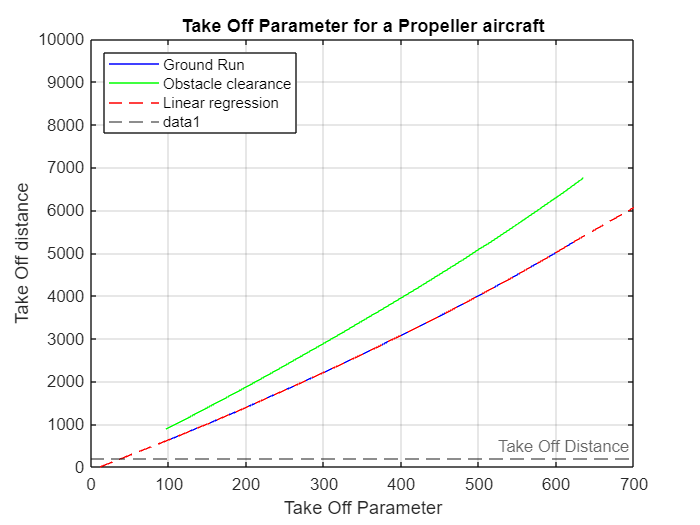

figure(2)
plot(para1,dist1,'Color','blue','DisplayName','Ground Run')
hold on
plot(para2,dist2,'DisplayName','Obstacle clearance',Color='green')
hold on 
plot(fit1(linspace(0,10000,1000)),linspace(0,10000,1000),'--','DisplayName','Linear regression','Color','red')
grid on
xlim([0,700])
ylim([0,10000])
xlabel('Take Off Parameter')
ylabel('Take Off distance')
title('Take Off Parameter for a Propeller aircraft')
yline(TO_dist,'--','Label','Take Off Distance')
saveas(gcf,'Takeoffparam.png')
legend(Location="northwest")

Landing Distance

Landing_dist = Clearance + 5*W_S_stall*(1/C_L_max_land)

Landing_dist = 198.8715

Cruise

q_cruise = 0.5*rho*v_cruise^2

q_cruise = 177.0125

W_S_cruise = q_cruise*sqrt(pi*e*AR*C_d_0)

W_S_cruise = 95.9103